% Mateusz Gietka 298941

% zadanie 2
j = 0.01;
b = 0.1;
k = 0.01;
r = 1;
l = 0.5;

A = [-r/l -k/l; k/j -b/j];
B = [1/l; 0];
C = [0 1];

Mac_ster = [ctrb( A,B)];
E = det(Mac_ster)

E = 4

% E != 0 => uklad sterowalny
    
Mp = 0.5;
t_r = 2;

t_const = 4/t_r;
reg_eps = -log(Mp)/sqrt(pi^2 + log(Mp)^2);
D = [1 2*reg_eps*t_const t_const^2];
p = roots(D);
K = place(A, B, p);
N = -inv(C*inv(A-B*K)*B);

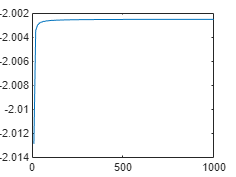

% zadanie 3
j = 0.01;
b = 0.1;
k = 0.01;
r = 1;
l = 0.5;

A = [-r/l -k/l; k/j -b/j];
B = [1/l; 0];
C = [0 1];
D=0;
 
sys = ss(A,B,C,D);
t=0:0.01:2;

Q = eye(2) .* [0;1];
R = eye(1) .* [0.00001];
 
[K, S, E] = lqr(A,B,Q,R);

 
N=-inv(C*inv(A-B*K)*B);


%{
a) Regulator LQR wykorzystuje model teoretyczny, nie rzeczywisty.
    Stąd uzyskanie przez niego odpowiedzi skokowej jest możliwe ale może łączyć się
    z wieloma błędnymi ustaleniami zmiennych wykorzystywanych w układzie.
b) Przy ograniczeniu sygnału sterującego zadana wartość sygnału wyjściowego nie zostanie osiągnięta.
c) Przy dodaniu wartości losowych układ przesterowuje się oraz wydłuża się jego czas stabilizacji.
d) Po dodaniu szumów układ nadal stabilizuje się z uchybem.
e)
%}

data = [];
step = 10;
for i = 1:step:1000
    R = [i];
    K = lqr(A, B, Q, R);
    data = [data eig(A-B*K)];
end

plot(step:step:1000, data(1,:))

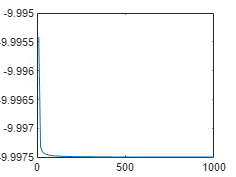

plot(step:step:1000, data(2,:))

% zadanie 4

j = 0.01;
b = 0.1;
k = 0.01;
r = 1;
l = 0.5;

A = [-r/l -k/l; k/j -b/j];
B = [1/l; 0];
C = [0 1];
D=0;

% a)
ob = det(obsv(A, C))

ob = -1

% obserwowalny

% b)
p = eig(A);
L = transpose(place(A', C', p * 10))

L = 	1.0e+03 *

    1.7660
    0.1080



%{ 
 d) Przy założeniu, że układ obserwatora jest idealny brak pętli
 wzmocnienia nie zmienia odpowiedźi
 e)Jeśli obserwator nie byłby idealny brak pętli wzmocnienia spowodowałby
 znaczaca rozbieznosc miedzy ukladem a jego modelem
 f) Bez sprzezenia wynik modelu nie pokrywa sie z wynikiem ukladu
 g) Im bardziej ujemne bieguny tym szybsza reakcja ukladu
 h) Przy zastosowaniu petli sprzezenia uklad nadal dziala dobrze
%}


Q = eye(2) .* [3;120];
R = eye(1) .* [100];
K = lqr(A, B, Q, R);
N = -inv(C*inv(A-B*K)*B)

N = 10.2176